# **Random Walker**

In mathematics, a [Random Walk](https://en.wikipedia.org/wiki/Random_walk) is a mathematical object, known as a stochastic or random process, that describes a path that consists of a succession of random steps on some mathematical space such as the integers. This file utilizes the DirectionsCoordinates file to run the random walk simulation. It's just a file I wrote to practice my Object Oriented Programming skills.

## **3D**

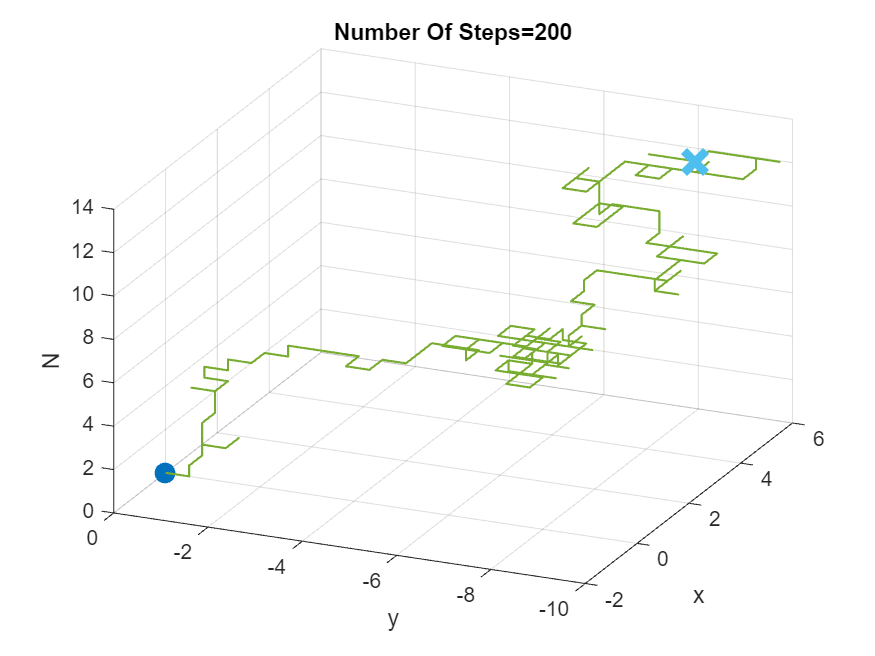

clear; close all; clc;
% first we set up the dialog box properties
prompt={'Enter The Coordinates Of Origin:','Directions{East,West,North,South,Up,Down}:','Enter Number Of Iterations:'};
dlgtitle='Initial Coordinates'; dims=[1 50];
% inputdlg Creates dialog box to gather user input {inputdlg(prompt,dlgtitle,dims)}
Input=inputdlg(prompt,dlgtitle,dims);

% now we assign our inputs to x,y,z,I,e,w,n,s,u,d
Coordinates=str2num(string(Input(1)));
Directions=str2num(string(Input(2)));
I=str2double(string(Input(3)));
OBJ3=DirectionsCoordinates(Directions);
[East,West,North,South,Up,Down]=OBJ3.DirProb();
[x,y,z]=OBJ3.PartCoordi(Coordinates);
X=x; Y=y; Z=z; % X,Y,Z contain the Origin point coordinates

figure('Name','RandomWalk','NumberTitle','off') % sets up the figure properties
rotate3d on % turns on rotate mode and enables rotation on all axes within the current figure
plot3(x,y,z,'o','LineWidth',5,'MarkerSize',5) % the Origin Marker
hold on

for i=2:I
    direction=randi(100); % generates random number from interval [1,100]
    switch direction
        case East
            x=x+0.5; X(i)=x; Y(i)=y; Z(i)=z;
        case West
            x=x-0.5; X(i)=x; Y(i)=y; Z(i)=z;
        case North
            y=y+0.5; X(i)=x; Y(i)=y; Z(i)=z;
        case South
            y=y-0.5; X(i)=x; Y(i)=y; Z(i)=z;
        case Up
            z=z+0.5; X(i)=x; Y(i)=y; Z(i)=z;
        otherwise
            z=z-0.5; X(i)=x; Y(i)=y; Z(i)=z;
    end
    
    plot3(X,Y,Z,'LineWidth',1,'MarkerSize',15)
    grid on % displays the major grid lines for the current axes
    xlabel('x')
    ylabel('y')
    zlabel('N')
    title('Number Of Steps='+string(i-1))
    drawnow % updates figures and processes any pending callbacks
end
plot3(x,y,z,'x','LineWidth',4,'MarkerSize',15) % the End Marker
hold off

## **2D**

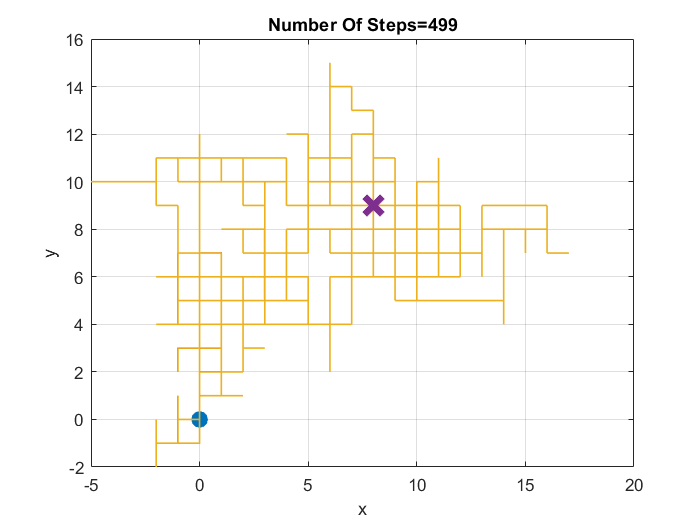

clear; close all; clc;

% first we set up the dialog box properties
prompt={'Enter The Coordinates Of Origin:','Directions{East,West,North,South}:','Enter Number Of Iterations:'};
dlgtitle='Initial Coordinates'; dims=[1 50];
% inputdlg Creates dialog box to gather user input {inputdlg(prompt,dlgtitle,dims)}
Input=inputdlg(prompt,dlgtitle,dims);

% now we assign our inputs to x,y,I,e,w,n,s
Coordinates=str2num(string(Input(1)));
Directions=str2num(string(Input(2)));
I=str2double(string(Input(3)));
OBJ2=DirectionsCoordinates(Directions);
[East,West,North,South]=DirProb(OBJ2);
[x,y]=PartCoordi(OBJ2,Coordinates);
X=x; Y=y; % X,Y contain the Origin point coordinates

figure('Name','RandomWalk','NumberTitle','off') % sets up the figure properties
plot(x,y,'o','LineWidth',5,'MarkerSize',5) % the Origin Marker
hold on

for i=2:I
    direction=randi(100); % generates random number from interval [1,100]
    % 0:=East 1:=West 2:=North 3:=South
    switch direction
        case East
            x=x+1; X(i)=x; Y(i)=y;
        case West
            x=x-1; X(i)=x; Y(i)=y;
        case North
            y=y+1; X(i)=x; Y(i)=y;
        otherwise
            y=y-1; X(i)=x; Y(i)=y;
    end
    
    plot(X,Y,'LineWidth',1,'MarkerSize',15)
    grid on % displays the major grid lines for the current axes
    xlabel('x')
    ylabel('y')
    title('Number Of Steps='+string(i-1))
    drawnow % updates figures and processes any pending callbacks
end
plot(x,y,'x','LineWidth',4,'MarkerSize',15) % the End Marker
hold off

## **The Gambler's Ruin**

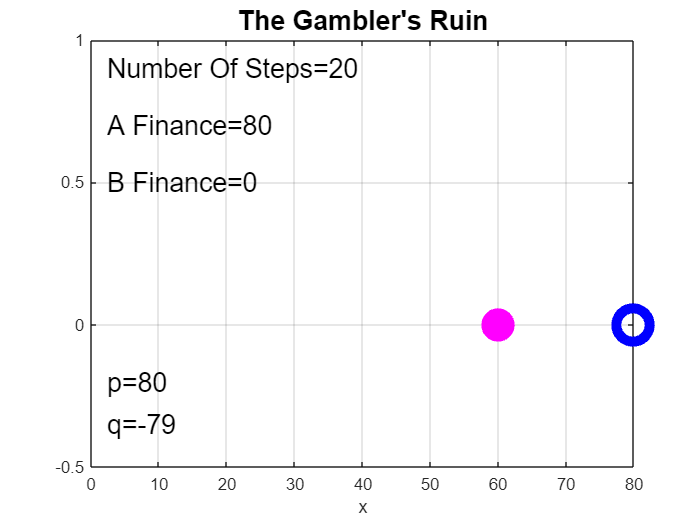

clear; close all; clc;

% first we set up the dialog box properties
prompt={'Enter The A Finance:','Enter The B Finance:','Enter P Probability Value:'};
dlgtitle='A and B Finance'; dims=[1 50];

% inputdlg Creates dialog box to gather user input {inputdlg(prompt,dlgtitle,dims)}
Input=str2double(string(inputdlg(prompt,dlgtitle,dims)));

% now we assign our inputs to A,B
a=Input(1); b=Input(2); p=Input(3); q=1-p; y=0; x=a;
R=p*100; A=a; B=b; Z=((3*(a+b))/100);

figure('Name',"The Gambler's Ruin",'NumberTitle','off') % sets up the figure properties
i=1;
while (x<a+b)&&(x>0)
    %pause(0.5);
    clf;
    r=floor((100)*rand(1,1))+1;
    if r<=R
        x=x+1;
        A=A+1;
        B=B-1;
    elseif r>R
        x=x-1;
        A=A-1;
        B=B+1;
    end
    plot(x,y,'o','Color','blue','LineWidth',6,'MarkerSize',20)
    hold on
    plot(a,y,'o','Color','magenta','LineWidth',10,'MarkerSize',10) % the Origin Marker
    axis([0 a+b -0.5 1]);
    grid on
    xlabel('x')
    title("The Gambler's Ruin",'FontSize',16)
    text(Z,0.9,"Number Of Steps="+string(i),'FontSize',16)
    text(Z,0.7,'A Finance='+string(A),'FontSize',16)
    text(Z,0.5,'B Finance='+string(B),'FontSize',16)
    text(Z,-0.2,'p='+string(p),'FontSize',16)
    text(Z,-0.35,'q='+string(q),'FontSize',16)
    i=i+1;
    drawnow
end
hold off